# [*developed function*]: load_data_IMU_MATRIX

This file contains the help documentation necessary to correctly import data from an inertial sensor of the *MATRIX* range.

Read a ".cvs file" (data format) generated by the *MATRIX* *app*. The *MATRIX* devices are *IMU* (*Inertial Measurement Unit*) sensors that measure accelerations, rotation speeds, body surface temperature, ambient temperature and heart rate.

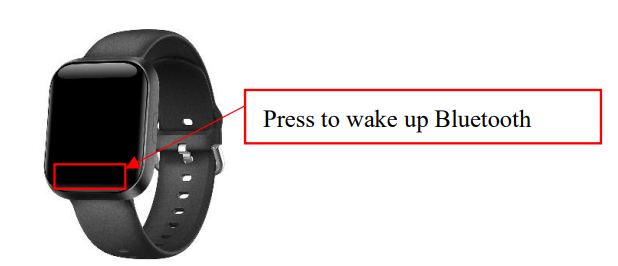

The following are the main features of the smartwatch; provided by the manufacturer *MATRIX*:

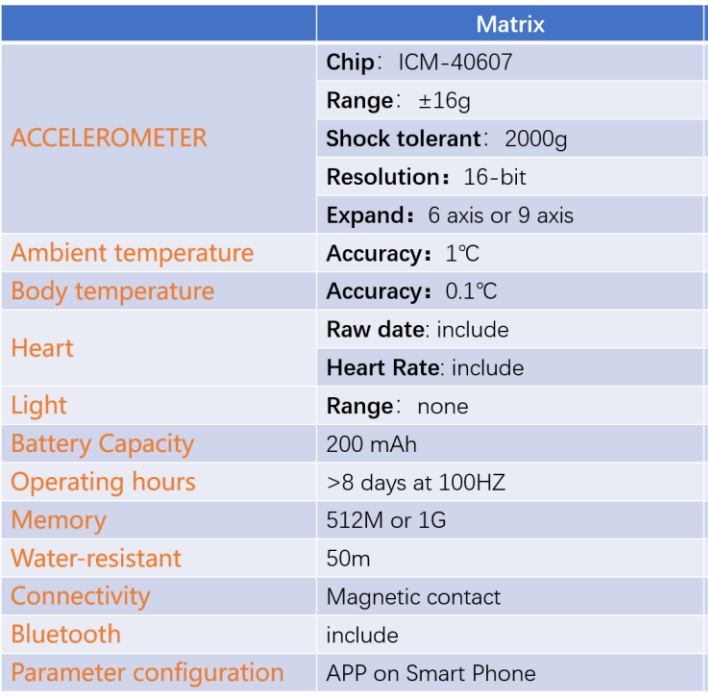

## 1.- Syntax

`[measurement]= load_data_IMU_MATRIX(file,idname)`

## 2.- Description

`[measurement]= load_data_IMU_MATRIX(file,idname)` `file` is the name of the file, and `idname` an identifier of the data structure where the data will be stored. 

The data structure that the function creates has the form:

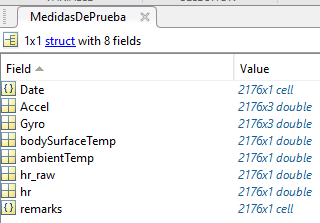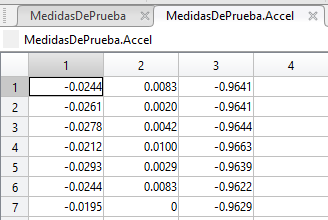

As an example, the figure above shows the data recorded for acceleration.

## 3.- Examples

### 3.1.- Reading of captured data

% Reading a data file
[TestMeasurements] = load_data_IMU_MATRIX('MeasurementsIMU_MATRIX_MATA1002195.csv',1000,1030)

TestMeasurements = struct with fields:
               Date: {31×1 cell}
              Accel: [31×3 double]
               Gyro: [31×3 double]
    bodySurfaceTemp: [31×1 double]
        ambientTemp: [31×1 double]
             hr_raw: [31×1 double]
                 hr: [31×1 double]
            remarks: {31×1 cell}


### 3.2.- Graphical representation of recorded data

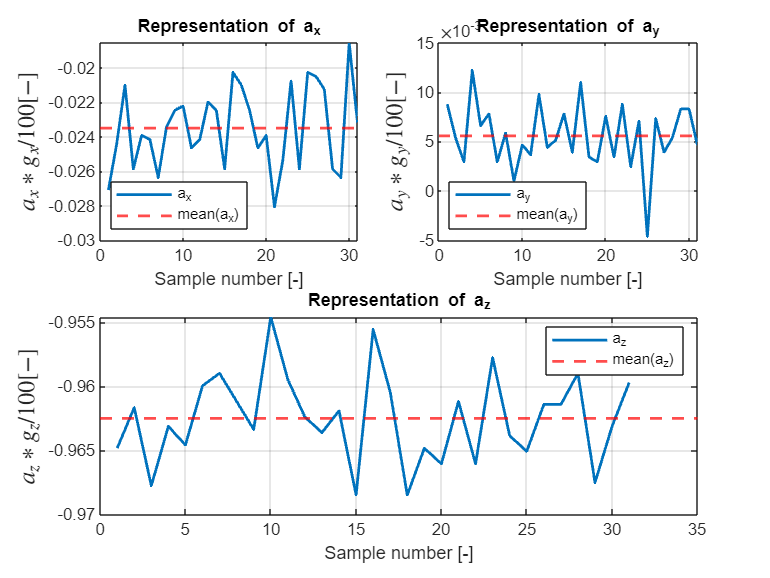

% Representation of acceleration measurements (axis X, Y, Z)
acceleration_x = TestMeasurements.Accel(:,1);                    % Loading of acceleration data on the X-axis
acceleration_y = TestMeasurements.Accel(:,2);                    % Loading of acceleration data on the Y-axis
acceleration_z = TestMeasurements.Accel(:,3);                    % Loading of acceleration data on the Z-axis

figure                                                           % Creation of a new figure
% Acceleration in the x-axis
subplot(2,2,1)                                                   % Activation of the first figure
plot(acceleration_x, 'LineWidth',1.5)                            % Graphical representation of acceleration on the X-axis
xlabel('Sample number [-]')                                      % Add label to the X-axis of the figure
ylabel('$a_x*g_x/100 [-]$','Interpreter','latex','FontSize',13)  % Add label to the Y-axis of the figure
grid on                                                          % Grid activation in the graphic display
title('Representation of a_x')                                   % Inclusion of title in the figure
yline(mean(acceleration_x),'r--','LineWidth',1.5)                % Represent average value of ax
legend('a_x', 'mean(a_x)', 'Location', 'southwest')              % Incorporation of a legend to the layout graphics

% Acceleration in the y-axis
subplot(2,2,2)                                                   % Activation of the second figure
plot(acceleration_y, 'LineWidth',1.5)                            % Graphical representation of acceleration on the Y-axis
xlabel('Sample number [-]')                                      % Add label to the X-axis of the figure
ylabel('$a_y*g_y/100 [-]$','Interpreter','latex','FontSize',13)  % Add label to the Y-axis of the figure
grid on                                                          % Grid activation in the graphic display
title('Representation of a_y')                                   % Inclusion of title in the figure
yline(mean(acceleration_y),'r--','LineWidth',1.5)                % Represent average value of ay
legend('a_y', 'mean(a_y)', 'Location', 'southwest')              % Incorporation of a legend to the layout graphics

% Acceleration in the z-axis
subplot(2,2,[3,4])                                               % Activation of the third and fourth figure
plot(acceleration_z, 'LineWidth',1.5)                            % Graphical representation of acceleration on the Z-axis
xlabel('Sample number [-]')                                      % Add label to the X-axis of the figure
ylabel('$a_z*g_z/100 [-]$','Interpreter','latex','FontSize',13)  % Add label to the Y-axis of the figure
grid on                                                          % Grid activation in the graphic display
title('Representation of a_z')                                   % Inclusion of title in the figure
yline(mean(acceleration_z),'r--','LineWidth',1.5)                % Represent average value of az
legend('a_z', 'mean(a_z)', 'Location', 'northeast')              % Incorporation of a legend to the layout graphics

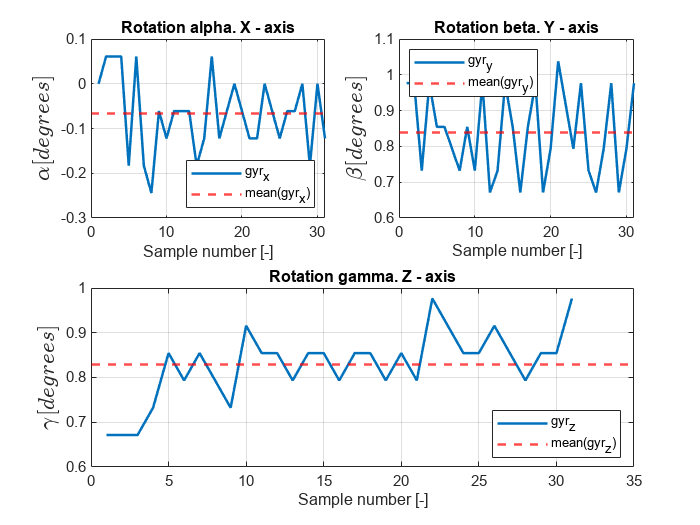

% Representation of measurements associated with gyroscopes (axis X, Y, Z)
gyroscope_x = TestMeasurements.Gyro(:,1);                         % Loading of gyroscope data on the X-axis
gyroscope_y = TestMeasurements.Gyro(:,2);                         % Loading of gyroscope data on the Y-axis
gyroscope_z = TestMeasurements.Gyro(:,3);                         % Loading of gyroscope data on the Z-axis

figure                                                            % Creation of a new figure

% Rotation in the x-axis
subplot(2,2,1)                                                    % Activation of the first figure
plot(gyroscope_x, 'LineWidth',1.5)                                % Graphical representation of rotation on the X-axis
xlabel('Sample number [-]')                                       % Add label to the X-axis of the figure
ylabel('$\alpha [degrees]$','Interpreter','latex','FontSize',14)  % Add label to the Y-axis of the figure
grid on                                                           % Grid activation in the graphic display
title('Rotation alpha. X - axis')                                 % Inclusion of title in the figure
yline(mean(gyroscope_x),'r--','LineWidth',1.5)                    % Represent average value of gyroscope_x
legend('gyr_x', 'mean(gyr_x)', 'Location', 'southeast')           % Incorporation of a legend to the layout graphics

% Rotation in the y-axis
subplot(2,2,2)                                                    % Activation of the second figure
plot(gyroscope_y, 'LineWidth',1.5)                                % Graphical representation of rotation on the Y-axis
xlabel('Sample number [-]')                                       % Add label to the X-axis of the figure
ylabel('$\beta [degrees]$','Interpreter','latex','FontSize',14)   % Add label to the Y-axis of the figure
grid on                                                           % Grid activation in the graphic display
title('Rotation beta. Y - axis')                                  % Inclusion of title in the figure
yline(mean(gyroscope_y),'r--','LineWidth',1.5)                    % Represent average value of gyroscope_y
legend('gyr_y', 'mean(gyr_y)', 'Location', 'northwest')           % Incorporation of a legend to the layout graphics

% Rotation in the z-axis
subplot(2,2,[3,4])                                                % Activation of the third and fourth figure
plot(gyroscope_z, 'LineWidth',1.5)                                % Graphical representation of rotation on the Z-axis
xlabel('Sample number [-]')                                       % Add label to the X-axis of the figure
ylabel('$\gamma [degrees]$','Interpreter','latex','FontSize',14)  % Add label to the Y-axis of the figure
grid on                                                           % Grid activation in the graphic display
title('Rotation gamma. Z - axis')                                 % Inclusion of title in the figure
yline(mean(gyroscope_z),'r--','LineWidth',1.5)                    % Represent average value of gyroscope_z
legend('gyr_z', 'mean(gyr_z)', 'Location', 'southeast')           % Incorporation of a legend to the layout graphics

***Date of last modification:**** 17/03/2023. SiMuR. EPI de Gijón. University of Oviedo.*

***Student:**** Alejandro Castellanos Alonso*